% Test analytical eddies
clear all

## 1. Extract tracks along the defined eddy path

% define eddy path: xe(t),ye(t) function handles as a function of time
x0 = 500e3; y0 = 0e3; vx = -2.0e3; vy = -0.5e3;
eddyPath_fun_t.xe = @(t) x0+vx*t;
eddyPath_fun_t.ye = @(t) y0+vy*t;

% define domain
x = linspace(-1e6,1e6,200); %meter
y = linspace(-500e3,500e3,200); %meter
totalDays = 366;

% non-arbitrary domain
% xe = eddyPath_fun_t.xe([0:totalDays-1])
% ye = eddyPath_fun_t.ye([0:totalDays-1])
% x = linspace(min(xe)-250e3,max(xe)+250e3,200);
% y = linspace(min(ye)-250e3,max(ye)+250e3,200);

% extract track - takes somes time bc it loads the entire track matrix
my_readdir = 'G:\My Drive\AlongTrack\';
alongtrackLatLon = alongtrackFromXYDomain(x,y,totalDays,lono=-40,readdir=my_readdir); %options: lato=24, lono=308

% If alongtrackFromXYDomain takes too long or you don't have
% JasonAlongTrack.nc file,
% To ensure that you're getting the correct directory:
% current_file_path = matlab.desktop.editor.getActiveFilename;
% [current_dir, ~, ~] = fileparts(current_file_path);
% load(strcat(current_dir,'\alongtrackLatLon.mat'))

## 2. Apply OSSE on your choice of an analytical eddy shape

%Output: alongtrack - contains arrays of lon,lat,x,y,t,ssh of OSSE 

#### Test 1 - Gaussian Eddy

% define eddy shape function handle
clearvars params
params.A = 0.15; %meter
params.L = 80e3; %meter

% eddy_model is a function handle with a chosen set of parameters (x,y,t)
% eddyShapeString = 'Gaussian';
eddy_model = analyticalEddyModel(eddyPath_fun_t,params);

% apply OSSE on an eddy_model function (x,y,t)
alongtrack = analyticalEddyModelOSSE(alongtrackLatLon,eddy_model);

video_name = 'eddy_field_gaussian';

#### Test 2 - Steady Elliptical Eddy:

clearvars params
params.A = 0.15;
%La,Lb are based on a desired eccentricity while roughly conserving mass 
L = 80e3;
lambda = 0.5;
La=L/sqrt(lambda);
params.La = L/sqrt(lambda);%0.4*2*L;
params.Lb = lambda*params.La;%0.2*2*L;

% eddy_model is a function handle with a chosen set of parameters (x,y,t)
% eddyShapeString = 'Ellipse';
eddy_model = analyticalEddyModel(eddyPath_fun_t,params);

% apply OSSE on an eddy_model function (x,y,t)
alongtrack = analyticalEddyModelOSSE(alongtrackLatLon,eddy_model);

video_name = 'eddy_field_steady_ellipse';

#### Test 3 - Precessing Elliptical Eddy:

clearvars params
params.A = 0.15;
%La,Lb are based on a desired eccentricity while roughly conserving mass 
L = 80e3;
lambda = 0.5;
La=L/sqrt(lambda);
params.La = L/sqrt(lambda);%0.4*2*L;
params.Lb = lambda*params.La;%0.2*2*L;
params.thetaDot= -10*pi/365; %similar to QG model ~5 rotations per year

% eddy_model is a function handle with a chosen set of parameters (x,y,t)
% eddyShapeString = 'Ellipse';
eddy_model = analyticalEddyModel(eddyPath_fun_t,params);

% apply OSSE on an eddy_model function (x,y,t)
alongtrack = analyticalEddyModelOSSE(alongtrackLatLon,eddy_model);

video_name = 'eddy_field_precessing_ellipse';

## 3. Plots and Videos of OSSE

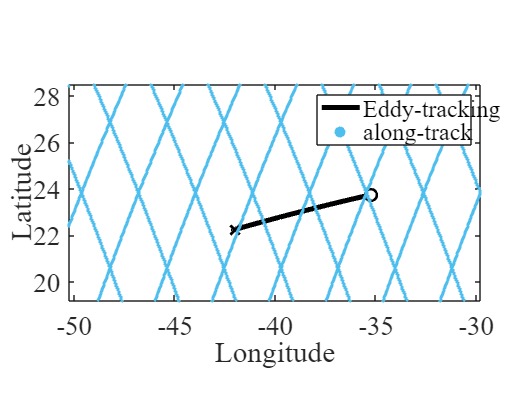

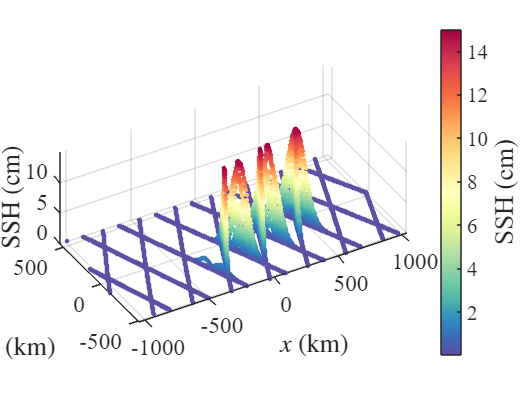

%% plot eddy path with alongtrack, and OSSE
plotAlongtrack(alongtrack,eddyPath_fun_t);

%% make video of the propagating eddy
makePropagatingVideo(x,y,totalDays,eddy_model,video_name)

## 4. Eddy composites and plots from full field

% eddy center from eddyPath
% Full field struct
fullfield.x = reshape(repmat(x',[1,length(y),totalDays]),[],1);
fullfield.y = reshape(repmat(y,[length(x),1,totalDays]),[],1);
fullfield.t = reshape(permute(repmat([1:totalDays]'-1,[1,length(x),length(y)]),[2,3,1]),[],1);
fullfield.ssh = eddy_model(fullfield.x,fullfield.y,fullfield.t);

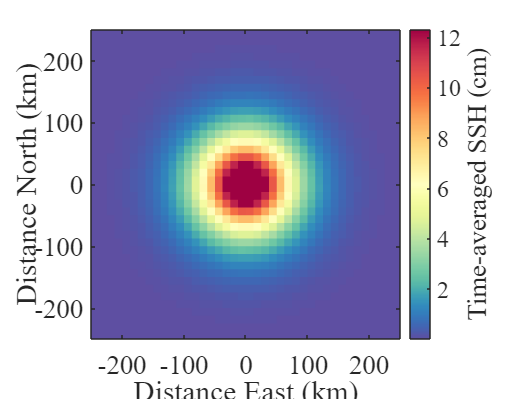

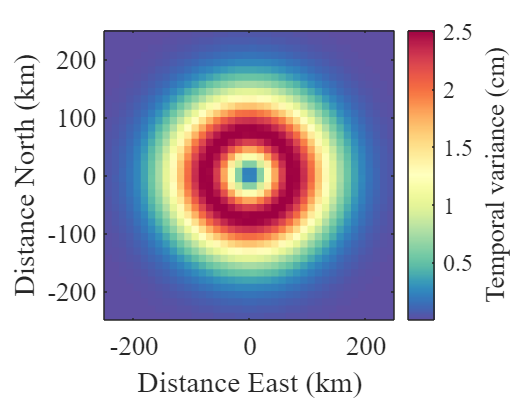

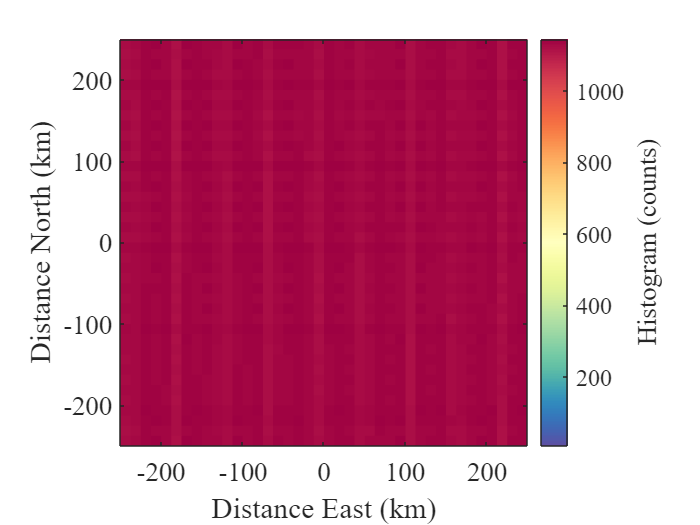

% time-averaged eddy composite from full field
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(fullfield,eddyPath_fun_t);% options: bin_size=12.5*1e3

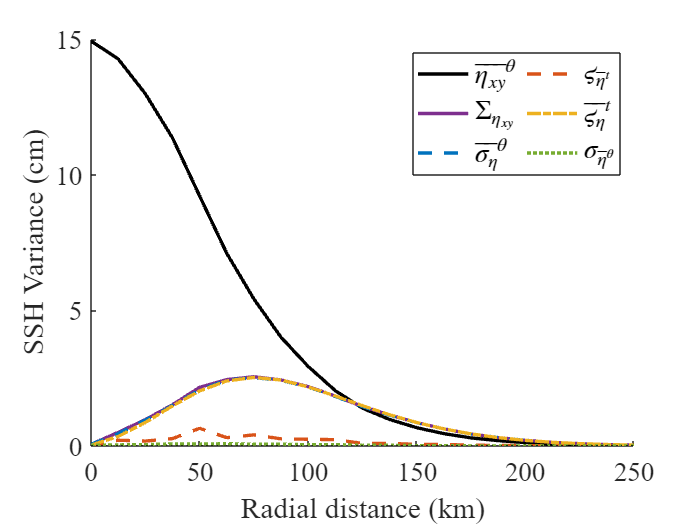

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(fullfield,eddyPath_fun_t);

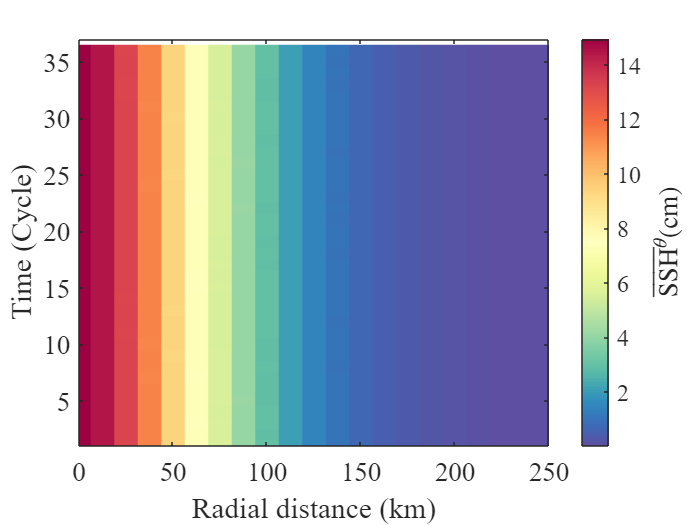

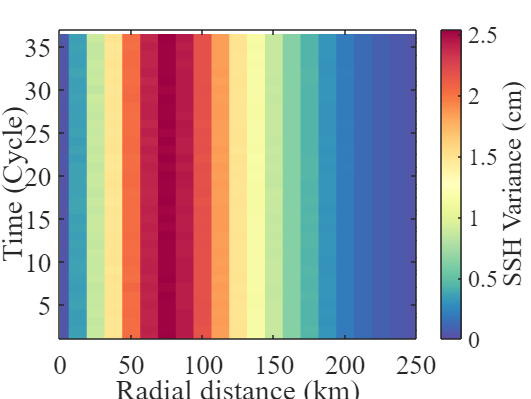

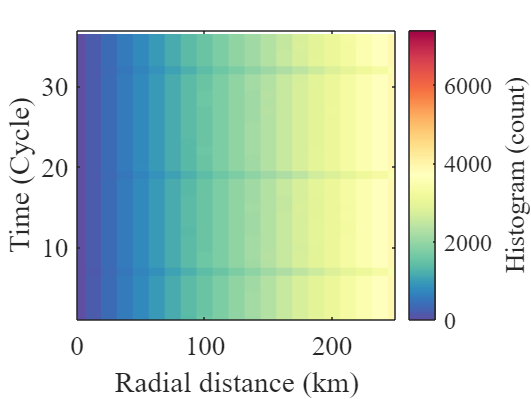

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(fullfield,eddyPath_fun_t);

## 4. Eddy composites and plots from OSSE

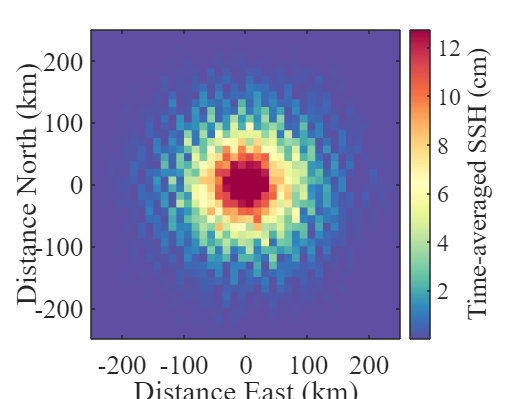

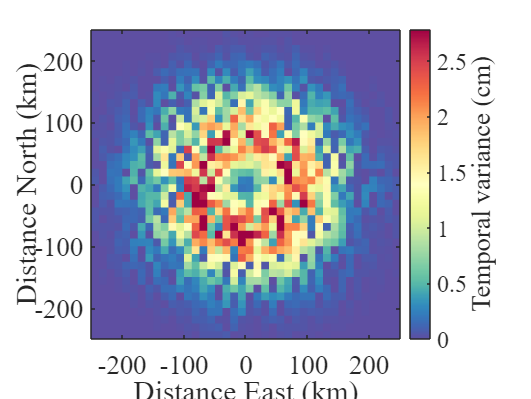

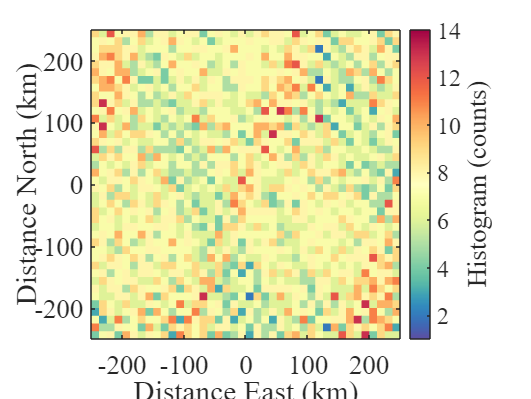

% eddy center from eddyPath
% time-averaged eddy composite from OSSE
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack,eddyPath_fun_t);% options: bin_size=12.5*1e3

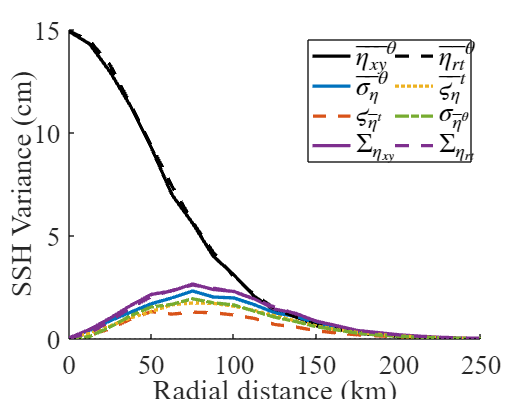

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack,eddyPath_fun_t);

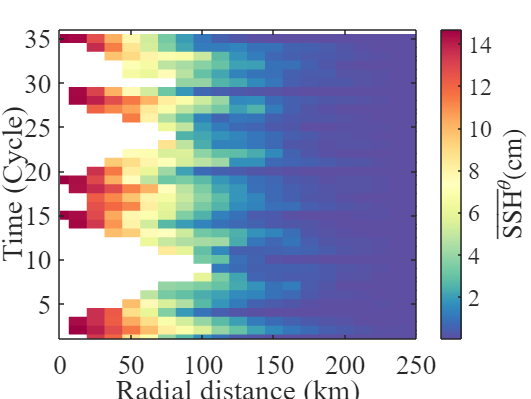

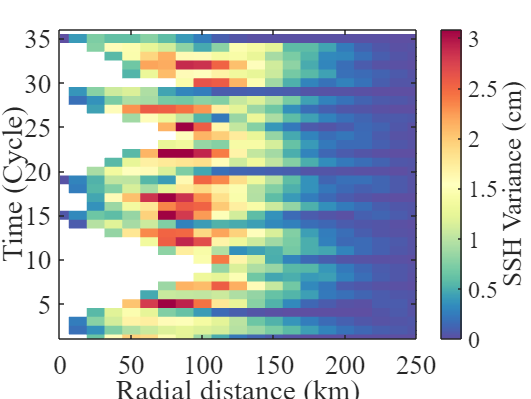

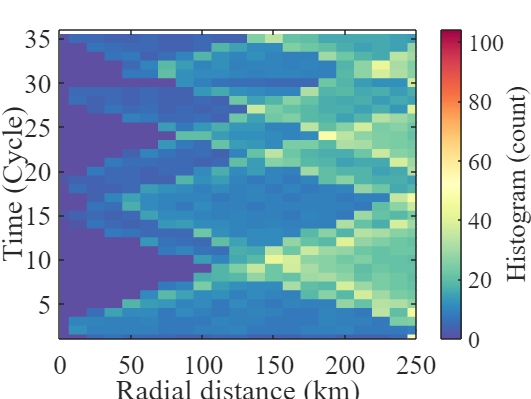

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## Relative vorticity and Streamfunction

First zero crossing at r = 71.73 km
Second zero crossing at r = 75.00 km


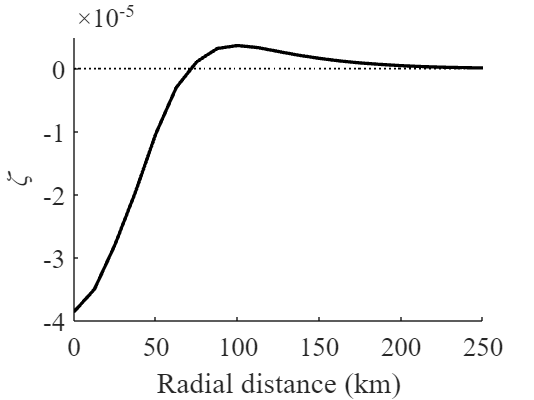

fullfield2D.x = x;
fullfield2D.y = y;
fullfield2D.t = [1:totalDays]-1;
fullfield2D.ssh = reshape(fullfield.ssh,[length(x),length(y),totalDays]);

[mz_zeta, rmid] = zetaProfile(fullfield2D,eddyPath_fun_t);

% streamfunction, energy, enstrophy
% psi=@(x,y,t) (g/fo)*eddy_model
% syms x y t
% u_sym=-diff(psi,y);
% v_sym=diff(psi,x);
% u=@(x,y,t) u_sym;

## Test parameters extraction

%% 
% replace center_xy with centroid of 90% max ssh
% [center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
plotParameters(alongtrack)


## 5. Convergence Rate

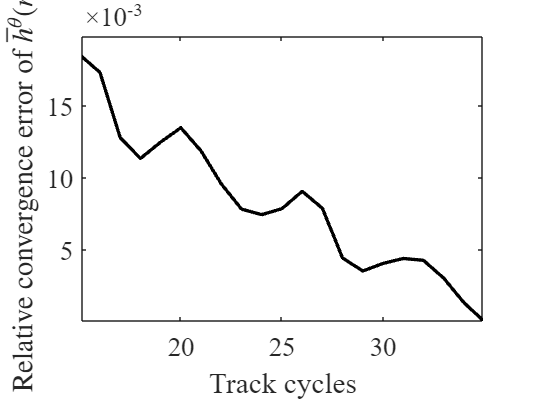

% how many cycles are needed to reach convergence to time-averaged profile
[convergence] = convergenceRate(mz_rt, numz_rt);

## 6. Gaussian fit

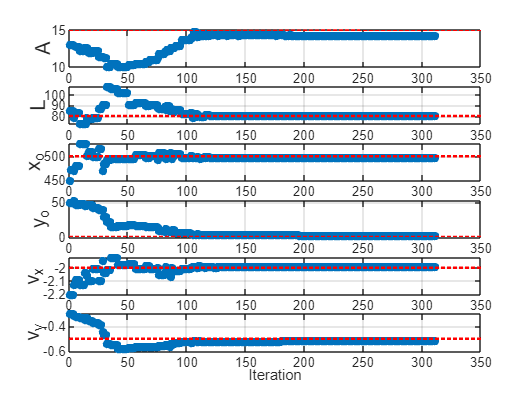

eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
true_params.A = params.A;
true_params.L = L;
true_params.x0 = x0;
true_params.y0 = y0;
true_params.cx = vx;
true_params.cy = vy;

initParams.A = true_params.A-0.02;
initParams.L = true_params.L+5e3;
initParams.x0 = true_params.x0-50e3;
initParams.y0 = true_params.y0+50e3;
initParams.cx = true_params.cx-0.2e3;
initParams.cy = true_params.cy+0.2e3;

plot_func = @(xtrans, optimValues, state) plotParamsIteration_ref(xtrans, optimValues, state, [], true_params);
it_options = optimset('OutputFcn', plot_func,'TolX',1e-3,'TolFun',1e-3);
paramsFit = FitAlongTrackXYToEddyModel(alongtrack, eddyFit_fun, initParams, it_options);

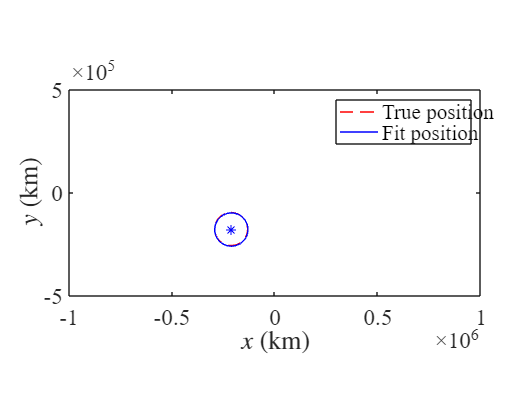

plotFitPosition(paramsFit,true_params)
xlim([min(x),max(x)]);ylim([min(y),max(y)])

%% time windowed fit
it_options = optimset('TolX',1e-3,'TolFun',1e-3);
[paramsCell, initParamsCell] = FitAlongTrackXYToEddyModelWindowed(alongtrack, eddyFit_fun, initParams, eddyPath_fun_t, it_options);

Previously accessible file "C:\Users\user\AppData\Local\Temp\Editor_zajio\LiveEditorEvaluationHelperE1230307634.m" is now inaccessible.

Error in LiveEditorEvaluationHelperE1230307634>@(t)x0+vx*t (line 9)

Error in FitAlongTrackXYToEddyModelWindowed (line 66)
initParams_window.x0 = eddyPath_fun_t.xe(

plotFitPosition(paramsCell,initParamsCell)
xlim([min(x),max(x)]);ylim([min(y),max(y)])
plotFitWindowed(paramsCell,true_params, eddyPath_fun_t)